# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

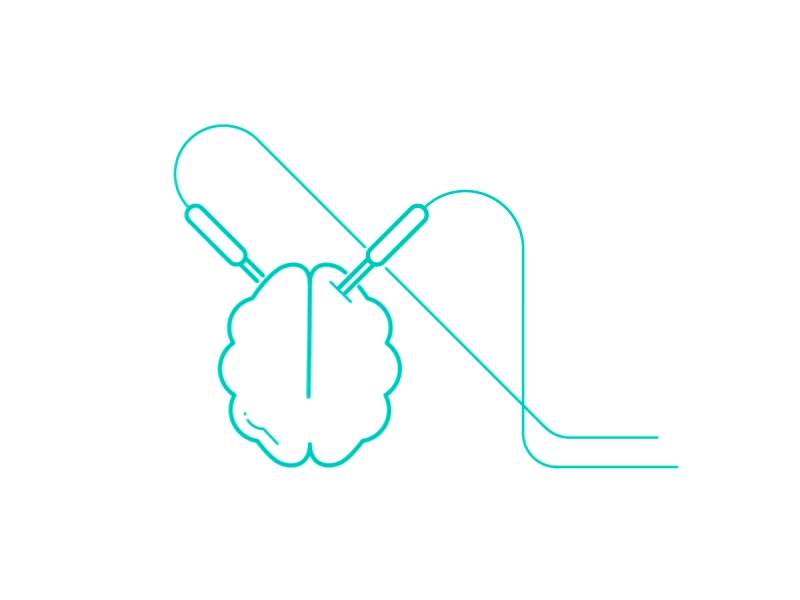

Deci uses Fieldtrip (Robert Oostenveld) as the backbone of its analysis with a few codes modified so it may not be compatible with other versions of Fieldtrip.

## **Getting Started**

To start, Save a new copy of this file (or Deci_NonVerbose for a shorten version).

Deci has 6 Stages, each segmented by it's own section with it's own list of parameters. I suggest using the "Run Section"  to work through each section step by step.

## 0. MainMenu

General Information used to find Raw Files director and Output Directory

#### Input Information

To start, You'll need to specify a Raw Data Folder with your Data within *.Folder.Raw *

Types of Raw formats compatible are [.dat, .eeg, .bdf, .cnt]

*.SubjectList *specifies which subjects in *.Folder.Raw *you'll like to analyze. [Cell Array of Strings], ['all' to specify all] or [ 'gui' to manually choose].

Deci = [];
Deci.File = mfilename;
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru1\RawData'];    
Deci.SubjectList = 'gui';  

If using "Run to End", the following gives you flexibility in where to start and how to proceed. Use 1 if using "Run Section".

Deci.Step               = 4;
Deci.Proceed            = true;                       

The following are smaller parameters 

Deci.PCom               = true;        % Activates Parallel Computing (if availible)

#### Output Information

Specify your output folder as* Folder.Version. *This is where all Processed Data will be sent to. This Folder will be automatically created if it does not exist.

At any step, you can define a new *Folder.Version *if you wish to for those analysis files to be stored seperately, i.e. "Data_noica","Data_ica" 

When MainMenu runs, a snapshot of this file's parameters will be saved as "Parameter.txt" in your *Folder.Version* Directory

Deci.Folder.Version     = ['C:\Users\User\Desktop\John\ProcessedData'];     

Deci = Checkor(Deci);

## 1. Trial Definitions

#### Terminology:

            Experimental Trials (ETs) - specific to the psychological experiment.

            Trial Definition - Information on how to sorts ET into specific Conditions.

            Collected Trials (CTs) - The output of Trial Definition.

            Conditions (Conds) - Each type of CT belongs to one type of Condition.

When EEG is first collected, you will end up with a Marker File and a Raw File. The Raw File is all but a matrix is of voltage that contains no important information on its own. The Marker File contains a list of events logged in the psychological experiment. Together, you'll use both files to segment your data into ETs and then sort them into CTs and Conds. 

#### Auto Trial Definition

Deci comes with a rudimentary Auto Trial Definition, however this comes with a few assumptions.

- There are unique markers signifying the start and end of your ETs that are not used anywhere else in .

- Any one of your *.DT.Starts* Codes will appear first in the Marker file before any *.DT.End *Codes appears.

- There are equal total amounts of *.DT.Starts* Markers and *.DT.End *Codes found in your Marker File.

- There is a specific marker you will timelock to and set your time axis as 0.

If you find that the above assumptions conflict with your needs [for example, you need CTs within a certain type of block but not others], you'll have to refer to Fieldtrip's ft_definetrial tutorial to create your cfg data.

Once you've created that File, save it to "..\Deci\Xtra_Fun" and set* .DT.Type * as that file's name and your CT will become Deci-compatible.

No other fields will be relevant for this case.

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {300};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {400};         %Cell Array of Markers for ETs End.

 The following fields works respectively, Each index corresponds to a single Condition. i.e. the first index of the *.DT.Conditions* corresponds to the first index of *.DT.Markers*.

- *.DT.Markers* -  1xConds Cell Array. Specfies which makers MUST be found in a ET for it be a CT. Use negatives to specify MUST NOT  be found.

- *.DT.Locks*    -  1xConds Char Vector. Specfies which of *.DT.Markers* is set as 0 in time.

- *.DT.Conditions* - 1xConds Char Vector. If two Conds share the same numerical value, they will collapse into one Cond.

    Deci.DT.Markers    = {[10] [11]};   
    Deci.DT.Locks      = [10 11];     
    Deci.DT.Conditions = [1 2];         

#### CTs Time of Interest

- *.DT.Toi* -  [Beg End in Secs], Times around *.DT.Locks *for each CT. ETs may have different trial lengths but all CTs within a Trial Definition will always be the same length.

If you get a "cannot read data after the end of the file" error, this is because the time length requested from *.DT.Toi *for the last trial is further than file's end. 

The only good solution to prevent this is to leave on-line data recording for a few seconds more after last trial finishes.

    Deci.DT.Toi        = [-2 2]; 


if Deci.Step <= 1
    DefineTrialor(Deci);
    if ~Deci.Proceed; return; end
end

## 2. PreProcessing Steps

While Trial Definition finds CTs, it does not go through your *Raw File *and cut out the relevant data to use.

This is done in this current step, along with steps to get the data ready to be analyzed.

Leave any option empty ,[], if the processing step is not desired.

####    Rereference channel to average of Implicit Electrode and Offline Reference

   Deci.PP.Imp                = 'RM:LM'; % 'Impicit Reference?[Implicit:RefChannels without Implicit]'
   Deci.PP.Ocu                = '';    % 'Ocular Reref?[Ref-Channels without Ref]'

#### Other Processing Steps

    Deci.PP.ScalingFactor       = [];               % Scalar, If the data needs to scale
    Deci.PP.HBP                 = [];               % Scalar,High-bandpass filter, in Hz.
    Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.
    
    Deci.PP.Repair              = [];                           % Structure, View and Repair (via interpoltation) Channels
%     Deci.PP.Repair.Type         = 'Manual';                   % String,'Manual' or 'Auto'
%     Deci.PP.Repair.Auto         = {};                         % Nx1 Subject cell array of Mx1 cells of M Channels to reject.

    Deci.PP.CleanLabels = 0; % Binary, normalize electrode names to be compatiable with Reinhart Lab's Needs.
    
    Deci.PP.HemiFlip   = [0 1 0 1 0 1 0 1 0 1 0 1 0 1]; % Might need to do CleanLabels to get channels to have numbers that can be flipped
    

if Deci.Step <= 2
    PreProcessor(Deci)
    if ~Deci.Proceed; return; end
end

## 3. Artifact Rejection

#### Individual Component Analysis

Will Reject Components and Alter Data for Analysis.

    Deci.Art.ICA.Reject                     = 1; % Whether or Not to do ICA
    Deci.Art.ICA.Eye.Chans           = {'BVEOG','RHEOG','AF7','AF8'}; 

#### Trial Artifacts

Auto-identification of Artifacts.

Does not rejection artifacts unless specified in Step 4, *.Analysis.ArtifactReject*

     Deci.Art.TR.Toi              = [-.5 -.2];          % Time Range of Interest to look for Artifacts
     Deci.Art.TR.rToi           = [-.5 1];              % Only available for Shifts.
 
     Deci.Art.TR.Eye                  = [];               % Comment the rest of .Eye to not do Eye Artifact Trial Rejection
%      Deci.Art.TR.Eye.Interactive      =  0;                % Enable Interactive Trial Artifact Rejection
%      Deci.Art.TR.Eye.Chans            = {'BVEOG','RHEOG','AF7','AF8'};    % 1xChan Cell Array of Ocular Eye Channels

    Deci.Art.TR.Muscle               = [];               % Comment the rest of .Muscle to not do Muscle Artifact Trial Rejection
%     Deci.Art.TR.Muscle.Interactive   = 0;                % Enable Interactive Trial Artifact Rejection

#### Manual Visual Artifact Rejection

Artification identification via inspection by Summary.

Does not rejection artifacts unless specified in Step 4, *.Analysis.ArtifactReject*

    Deci.Art.Manual = [];
%     Deci.Art.Manual.Toi              = [-.5 -.2];
%     Deci.Art.Manual.rToi              =[-.5 1];  % Only available for Shifts.

   if Deci.Step <= 3
    Artifactor(Deci);
    if ~Deci.Proceed; return; end
end

## 4. Analysis

#### Currently functionalites

Time-Frequency

            TotalPower      [only through wavelet decomposition]

            ITPC                [only through wavelet decomposition]

Event-Related Data

Power-Related Potential  

Cross-Frequency Coupling 

            Phase-Locking Value

            Phase-Amplitude Coupling

#### General Set-Up

    Deci.Analysis.ArtifactReject     =0;                    % Specify whether or not to Apply Trial Rejection
    Deci.Analysis.Channels           = {'Fz','Cz','C3','O1'};                % Cell array of channels or 'all'
    Deci.Analysis.Laplace            =0;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
    
    Deci.Analysis.Redefine = [];                             % Only available for Shifts.
%     Deci.Analysis.Redefine.Bsl = [-.5 -.2];
%     Deci.Analysis.Redefine.ERPToi = -.5;
    

#### Time-Frequency Analysis

    This *.Freq* Structure follows exactly ft_freqanalysis but may need to modify due to the *.Freq.Toi* parameter (instead of lowercase *.Freq.toi*)

    Deci.Analysis.Freq               = [];           % Comment the rest of .Freq to not do Fourier Transformation
    Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
    Deci.Analysis.Freq.foi           = exp(linspace(log(2),log(40),40));       % Frequency of Interest
    Deci.Analysis.Freq.width         = 7 ;           % Width
    Deci.Analysis.Freq.gwidth        = 4;            % Gwidth
    Deci.Analysis.Freq.Toi           = [-.5 1];       % Time Range
    
    Deci.Analysis.Freq.Redefine = 0;   % 1 for Both BSL and Freq, or 2 just BSL % Only available for Shifts.
    Deci.Analysis.Freq.kptrls   = 0;

#### Event Related Potential Analysis

  Note that entire Time Range will be analyzed.

    Deci.Analysis.ERP                = [];
    Deci.Analysis.ERP.raw            = 0;

#### Cross-Frequency Coupling 

            Requires* .Freq * to have been done.

    Deci.Analysis.Freq.CFC = [];
    Deci.Analysis.Freq.CFC.chanlow = {'Fz' 'Cz'};
    Deci.Analysis.Freq.CFC.chanhigh = {'C3' 'O1'}; %Try not to do all to all if you have more than 10 chans
    
    Deci.Analysis.Freq.CFC.latencyhigh = [-.5 .5]; %no implementation yet to check for edge artifactsm so be careful
    Deci.Analysis.Freq.CFC.latencylow = [-.5 .5];
    
    Deci.Analysis.Freq.CFC.Freqhigh = 'beta';
    Deci.Analysis.Freq.CFC.Freqlow = 'theta';
    
    Deci.Analysis.Freq.CFC.timebin = 5;
    Deci.Analysis.Freq.CFC.methods = {'mi','plv'};  % can only currently handle 'plv' or 'mi'(pac)
    Deci.Analysis.Freq.CFC.keeptrials =  'no';
        
    %     cfg.method     = string, can be
    %                     'coh' - coherence [Fourier-Fourier]
    %                     'plv' - phase locking value [phase-phase of amp]
    %                     'mvl' - mean vector length [phase-amp]
    %                     'mi'  - modulation index  [phase-amp]
    %                     'cs_cc'  - circstats circular-circular [phase-phase]
    %                     'cs_cl'  - circstats circular-linear [phase-amp]

####  Not Available

    Deci.Analysis.EvokedPower        = 0; %Not Available

if Deci.Step <= 4
    Analyzor(Deci)
    if ~Deci.Proceed; return; end
end

## 5. Plotting

#### General Set-Up

    Deci.Plot.GA =  0;                       % 0 for Individual Plots, 1 for GrandAverage
    Deci.Plot.Scale = 'linear';
    Deci.Plot.Save = [];
    Deci.Plot.Save.Format =  'fig';

#### Math

Allows plotting of new Conds that computed by mathically operations done on current Conds. Those new Conds can also contribute to creation of more new Conds

            Examples: 4 Conds created

            *.Plot.Math.Form* = {'[x1+x3]','[x2+x4]','x6-x5'}; 

            in this example sum Cond 1+3 creates Cond 5, Cond 2+4 creates Cond 6 and together Cond 5+6 creates Cond 7

    Deci.Plot.Math = [];
%   Deci.Plot.Math.Form = {'[x1+x3]','[x2+x4]','x6-x5'};    % in this example sum of Cond1 and Cond3 makes Cond 5,                
    Deci.Plot.Math.Type = 0;                    % 0 = no math plots, 1 = only math plots, 2 = both math and single plots
    

#### Time-Frequency

    Deci.Plot.Freq = [];
    
    
    Deci.Plot.Freq.Plot = 0;                % 1 or 0 to do Freq Plots
    Deci.Plot.Freq.Foi = [3 4.5]; 
    Deci.Plot.Toi = [0 .8];
    Deci.Plot.Freq.Channel = [{'VEM'  'HEM'  'F3'  'F4'  'C3'  'C4'  'P3'  'P4'  'PO3'  'PO4'  'O1'  'O2'  'OL'  'OR'  'T3'  'T4' 'T5'  'T6'  'Fz'  'Cz'  'Pz'  'LM' 'RM'}];   
    Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'
     
    Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
    Deci.Plot.Freq.Roi = [];          % use 'maxmin','maxabs or [min max] to set.
    Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

    Deci.Plot.Freq.Topo = 1;
    Deci.Plot.Freq.Square = 1;
    

####   Time-Frequency Wires

    Deci.Plot.Freq.Wires = [];
%         Deci.Plot.Freq.Wires.Collapse = 'Time';        %Which Dim to Collapse 'Time' or 'Freq'
%         Deci.Plot.Freq.Wires.avgoverfreq = 'no';
%         Deci.Plot.Freq.Wires.avgovertime= 'yes';
%         Deci.Plot.Freq.Wires.frequency = [4 8];
%         Deci.Plot.Freq.Wires.latency = [.1  .5];
%         Deci.Plot.Freq.Wires.nanmean = 'no';
    

####   ERP

    Deci.Plot.ERP = []; %Not Available to plot
    %     Deci.Plot.ERP.Channel = 'all';              % Cell array of channels or 'all'

####   PRP

    
    Deci.Plot.PRP = [];                     %Requires .Freq/.ERP to be filled out
    %Power related Potential
    %Plot 1 = Collapsed-Frequency/Channel Freq.Type Data
    %plot 2 = Collapsed-Channel           ERP Data
    %plot 3 = Condition-Specific Timepoint by Timepoint Freq-ERP coorelation across subjects
    %plot 4 = Collapsed-Time/Freq/Channel Condition-Specific Subject by Subject plotted along Freq-YAxis, ERP-XAxis
    %Changes .GA into 0
    %     Deci.Plot.PRP.label = 1;                %Whether or Not to add subject info on plot 4
    %     Deci.Plot.PRP.ScatterToi = [.3 .7];     %Time range for plot 4
    

####     Cross-Frequency Coupling

    Deci.Plot.CFC = []; 
    Deci.Plot.CFC.method = 'plv';
    Deci.Plot.CFC.Topo = 1;
    Deci.Plot.CFC.Square = 1;
    Deci.Plot.CFC.Hist = 1;
    Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

if Deci.Step <= 5
    Plottor(Deci);
    if ~Deci.Proceed; return; end
end